**Calculation of magnetic field strength around disk cross-section:**

If we consider a circular disk of radius, a, with applied uniform current density, j, passing through along the disk axis, the radial field is given by the following expression:


$$dH(X,Y) = \frac{j \cdot dxdy}{2\pi \cdot r}$$
  

If we assume that the current density is homogenous  and the object is radial symmetric, j can be replaced by $j=\frac{I}{A}=\frac{I}{\pi a^2}$ and dxdy, in polar coordinates is $dxdy=rdrd\phi$. Since the system is radially symmetric, the magnetic field component can only be in the $\hat{\phi}}$ direction and thus:


$$dH(X,Y) = \frac{Idrd\phi}{2\pi^2a^2}\hat{\phi}}$$


Integrating over the area of the disk cross-section we can arrive at an expression for H *inside the disk*:


$$H=\int_{0}^{2\pi}\int_{0}^{R}\frac{Idrd\phi}{2\pi^2a^2} \hat\phi$$


The integration is simple to perform and we can replace the unit vector with cartesian unit vectors such that $\hat{\phi} =- sin\phi \hat{x} + cos \phi \hat{y}$ or:


$$H=-\frac{IR}{2\pi a^2}(- sin\phi \hat{x} + cos \phi \hat{y})$$


Replacing $cos\phi$ and $sin\phi$ with the requisite definitions of $cos\phi=\frac{x}{R}$ and $sin\phi = \frac{y}{R}$  as well as $R^2 = x^2 +y^2$ :

So inside the conductor, the magnetic field looks like:$H = \frac{I}{2\pi a^2}(y \hat{x}-x\hat{y})$

Outside the conductor, the field follows a slightly different expression such that:

$H =- \frac{I}{2\pi r'} \hat{\phi} $  where $r'$ is the radial distance from the conductor surface. Using the above and earlier definitions this becomes:


$$H = \frac{I}{2 \pi (x^2+y^2)}(y\hat{x}-x\hat{y})$$


%Script calculates and plots the magnetic field strength vectors
%surrounding a disk cross section with a given radius a and applied current
%I. 


**Properties of circular disk:**

%radius of disk cross section in nanometers
a = 100;

%current through disk cross section in A
I=0.49;


**Position of desired field measurement:**

xstr = "100";
ystr = "0";

xpos2 = str2double(xstr);
ypos2 = str2double(ystr);

hxpos2 = circxfield(a,xpos2,ypos2,I) * 10^9;
hypos2 = circyfield(a,xpos2,ypos2,I) * 10^9;




**Magnetic field strength at (X,Y):**

magnitude2 = sqrt((hypos2)^2 + hxpos2^2);

fprintf("The X field component at \n (%.2f,%.2f) is: %.4f A/m", xpos2,ypos2,hxpos2)

The X field component at 
 (100.00,0.00) is: 0.0000 A/m


fprintf("The Y field component at \n (%.2f,%.2f) is: %.4f A/m", xpos2,ypos2,hypos2)

The Y field component at 
 (100.00,0.00) is: -779859.2212 A/m

fprintf("The magnitude of the field strength a \n (%.2f,%.2f) is: %.4f A/m", xpos2, ypos2, magnitude2)

The magnitude of the field strength a 
 (100.00,0.00) is: 779859.2212 A/m

**Display Parameters:**

arrows = 19;
markersize = 0.95;
a3 = 3*a;
plotrange = 243;


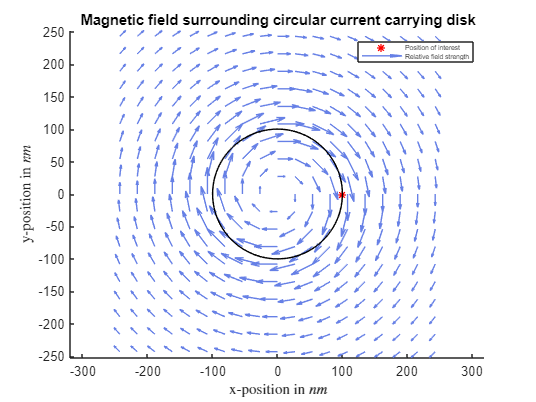

%Plotting range and number of arrows, and matrix representation of (x,y)
%ranges:
ticks = linspace(-plotrange,plotrange,arrows);
[XX,YY] = meshgrid(ticks,ticks);


%magnetic field components produced by disk:

%loops through grid of (x,y) values and creates a matrix of both x and y
%magnetic field components:

n = numel(ticks);
hxmatrix = zeros(n);
for i=1:n
for j=1:n
    hxci = circxfield(a,ticks(j),ticks(i),I);
    hxmatrix(i,j)=hxci;

end
end

hymatrix = zeros(n);
for i=1:n
for j=1:n
    hyci = circyfield(a,ticks(j),ticks(i),I);
    hymatrix(i,j)=hyci;

end
end




%plots  quiver plot of field strength vectors centred at (0,0) with a disk
%superimposed to show the position and relative size of the disk

scatter(xpos2,ypos2,'r', "*", "LineWidth", markersize)
hold on
quiver(ticks,ticks,hxmatrix,hymatrix, 1.2,"color",[0.4,0.5,0.9])
hold off
pos = [-a -a 2*a 2*a];
rectangle('Position',pos,'Curvature',[1 1])
xlabel("x-position in $nm$", "Interpreter","latex")
ylabel("y-position in $nm$", "Interpreter","latex")
title("Magnetic field surrounding circular current carrying disk")
leg2 = legend("Position of interest","Relative field strength");
set(leg2, "fontsize", 5)
axis equal



%Calculates the y Vector component of magnetic field surrounding a circular
%disk of radius a:


function [Hy] = circyfield(a,X,Y,I)
    %a is the radius of the disk
    %X is x position
    %Y is y position
    %I is the value of current through the surface 
    %Returns x component of magnetic field
    p=pi;

    if (X^2+Y^2) >= a^2
        Hy = (I/(2*p))*(1/((X^2+Y^2))) *(-X);

    else 
        Hy = (I/(2*p*(a^2)))*(-X);

    end
end


%Calculates the x Vector component of magnetic field surrounding a circular
%disk of radius a:

function [Hx] = circxfield(a,X,Y,I)
    %a is the radius of the disk
    %X is x position
    %Y is y position
    %I is the value of current through the surface 
    %Returns x component of magnetic field
    p=pi;

    if (X^2+Y^2) >= a^2
        Hx = (I/(2*p))*(1/((X^2+Y^2))) *(Y);

    else 
        Hx = (I/(2*p*(a^2)))*(Y);

    end
        
end